## Load data sets

Dose_D0 = load('Dose_D0.mat');
Dose_D_min = load('Dose_D_min.mat');
Dose_D_max = load('Dose_D_max.mat');
Dose_ci_min = load('Dose_ci_min.mat');
Dose_ci_max = load('Dose_ci_max.mat');
Dose_XZ_default = load('Dose_XZ_default.mat');

Dose_YZ_default = load('Dose_YZ_default.mat');
Dose_XZ_default_85d = load('Dose_XZ_default_85d.mat');
Dose_YZ_default_85d = load('Dose_YZ_default_85d.mat');
%Dose_XZ_default_84d_cum = Dose_XZ_default.Dose_cum + Dose_XZ_default_84d.Dose_after17d
%Dose_YZ_default_84d = load('Dose_YZ_default_after17d.mat');
%Dose_YZ_default_84d_cum = Dose_YZ_default.Dose_cum + Dose_YZ_default_84d.Dose_after17d

# XYZ graphs 85 days

## 1.1 Dose profile plot 2D 85 days: XZ

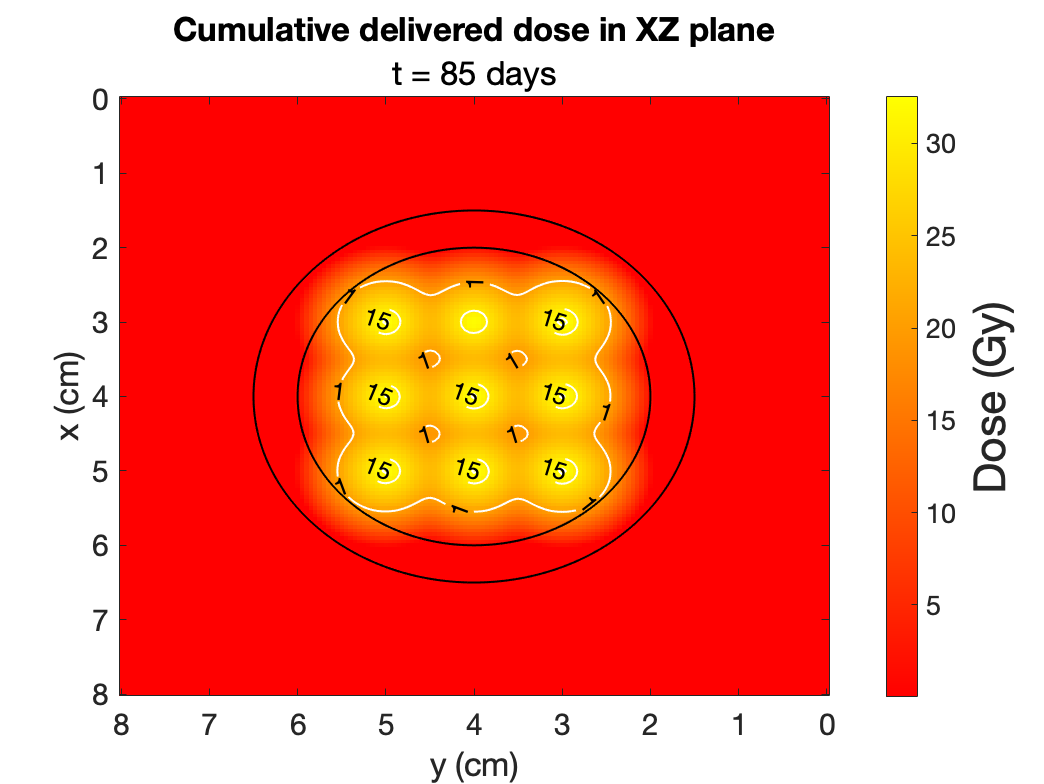

[xc2, yc2] = circle([4 4], 2,1200); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
[xc, yc] = circle([4 4], 2.5,1200); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
x_Dose = linspace(0,8,161);
y_Dose = linspace(0,8,161);
%Dose_D0 = load('Dose_D0.mat');
%Dose_cum = Dose_cum + Dose_after17d;

figure
imagesc(x_Dose,y_Dose,Dose_XZ_default_85d.Dose_grid_85d)
colormap('autumn')
hold on
[c,H] = contour(x_Dose,y_Dose,Dose_XZ_default_85d.Dose_grid_85d,[1 15 30 60 120],'ShowText','off','LineWidth',1,'LineColor','w');
plot(xc, yc, '-','linewidth',1,'Color','k');
plot(xc2 , yc2, '-','linewidth',1,'Color','k');
clabel(c,H,'FontSize',12,'Color','k','Margin',10,'LabelSpacing',60)
xlabel('x (cm)','FontSize',22)
ylabel('y (cm)','FontSize',22)
title('Cumulative delivered dose in XZ plane','FontSize',27)
txt = {'t = 85 days'};
subtitle(txt)
view([90 90])
set(gca,'ColorScale','log')
clb = colorbar;
set(get(clb,'label'),'string','Dose (Gy)','FontSize',22);
set(gca,'XTick',[0 1 2 3 4 5 6 7 8],'XTickLabel',{'0','1','2','3','4','5','6','7','8'},'YTick',[0 1 2 3 4 5 6 7 8],'YTickLabel',{'0','1','2','3','4','5','6','7','8'})
set(gca,'FontSize',15)

## 1.2 Dose profile plot 2D 85 days: YZ

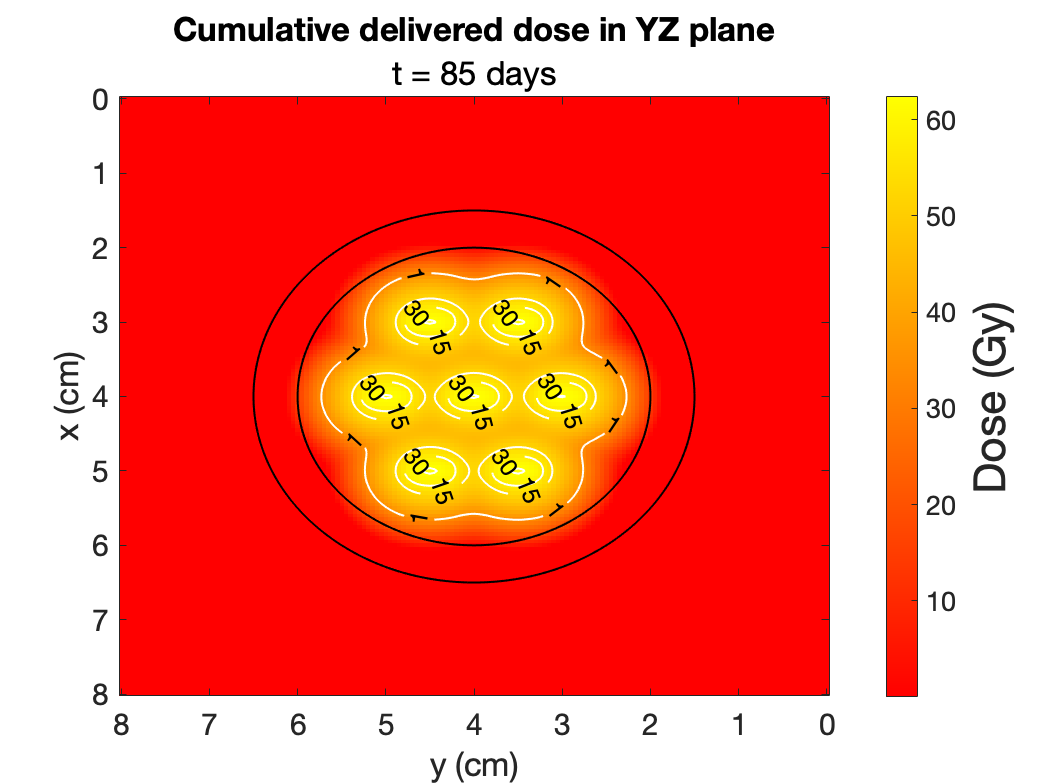

[xc2, yc2] = circle([4 4], 2,1200); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
[xc, yc] = circle([4 4], 2.5,1200); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
x_Dose = linspace(0,8,161);
y_Dose = linspace(0,8,161);
%Dose_D0 = load('Dose_D0.mat');
%Dose_cum = Dose_cum + Dose_after17d;

figure
imagesc(x_Dose,y_Dose,Dose_YZ_default_85d.Dose_grid_85d)
colormap('autumn')
hold on
[c,H] = contour(x_Dose,y_Dose,Dose_YZ_default_85d.Dose_grid_85d,[1 15 30 60 120],'ShowText','off','LineWidth',1,'LineColor','w');
plot(xc, yc, '-','linewidth',1,'Color','k');
plot(xc2 , yc2, '-','linewidth',1,'Color','k');
clabel(c,H,'FontSize',12,'Color','k','Margin',10,'LabelSpacing',60)
xlabel('x (cm)','FontSize',22)
ylabel('y (cm)','FontSize',22)
title('Cumulative delivered dose in YZ plane','FontSize',27)
txt = {'t = 85 days'};
subtitle(txt)
view([90 90])
set(gca,'ColorScale','log')
clb = colorbar;
set(get(clb,'label'),'string','Dose (Gy)','FontSize',22);
set(gca,'XTick',[0 1 2 3 4 5 6 7 8],'XTickLabel',{'0','1','2','3','4','5','6','7','8'},'YTick',[0 1 2 3 4 5 6 7 8],'YTickLabel',{'0','1','2','3','4','5','6','7','8'})
set(gca,'FontSize',15)

## 2. Intersection through centre 85 days: XYZ

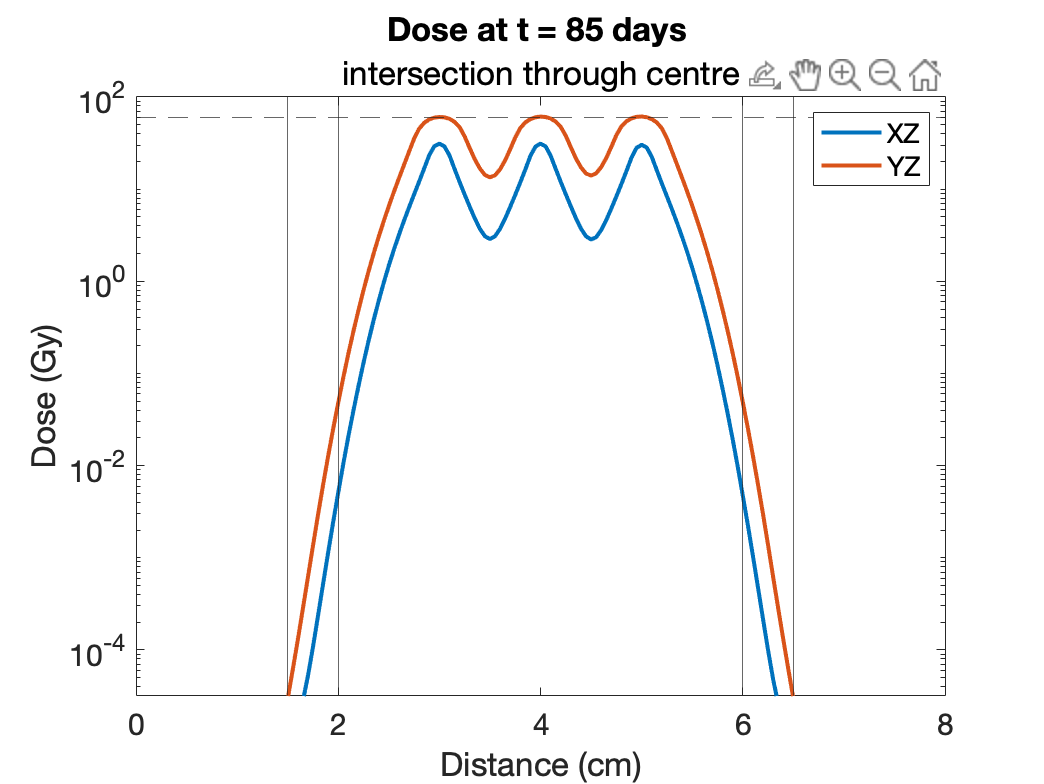

figure
plot(x_Dose,Dose_XZ_default_85d.Dose_grid_85d(:,81),'LineWidth',2)
hold on
plot(x_Dose,Dose_YZ_default_85d.Dose_grid_85d(:,81),'LineWidth',2)
yline(60,'--')
xline(2);
xline(6);
xline(1.5);
xline(6.5);
ylabel('Dose (Gy)')
xlabel('Distance (cm)')
title('Dose at t = 85 days ')
subtitle('intersection through centre')
set(gca,'YScale','log')
legend('XZ','YZ')
set(gca,'FontSize',15)
ylim([10^(-4.5) 10^2])
xlim([0 8])

## 4. Calculate GTV, PTV, PTV + 1 cm values of Dose

r = [2 2.5 3.5];
centretumor = [4 4];
%Dose_YZ_84d = Dose_YZ_default.Dose_time(:,409) + Dose_YZ_default_84d.Dose_after17d_array(:,end) ;
%Dose_XZ_default_84d_reshape = reshape(Dose_XZ_default_cum_84d(:,:),[],1);

[modelData] = dd6_2_Dose_t_average(Dose_XZ_default_85d.Dose_array_85d,x2,y2,r(1),r(2),r(3),centretumor(1)); % C values (max,min,average) in GTV

averageD_GTV = 4.1709

minD_GTV = 0.0037

maxD_GTV = 32.5072

averageD_PTV = 0.0303

minD_PTV = 1.3685e-05

maxD_PTV = 0.6351

averageD_1cm = 1.9336e-05

minD_1cm = 8.0947e-06

maxD_1cm = 3.7518e-04

Output argument "modelData" (and possibly others) not assigned a value in the execution with "dd6_2_Dose_t_average" function.

[modelData] = dd6_2_Dose_t_average(Dose_YZ_default_85d.Dose_array_85d,x2,y2,r(1),r(2),r(3),centretumor(1)); % C values (max,min,average) in GTV

averageD_GTV = 10.1765

minD_GTV = 0.0025

maxD_GTV = 62.3296

averageD_PTV = 0.0053

minD_PTV = 1.3759e-05

maxD_PTV = 0.0919

averageD_1cm = 4.7876e-06

minD_1cm = 3.0022e-07

maxD_1cm = 5.5190e-05

Output argument "modelData" (and possibly others) not assigned a value in the execution with "dd6_2_Dose_t_average" function.

# XYZ graphs 17 days

## 1.1 Dose profile plot 2D 17 days: XZ

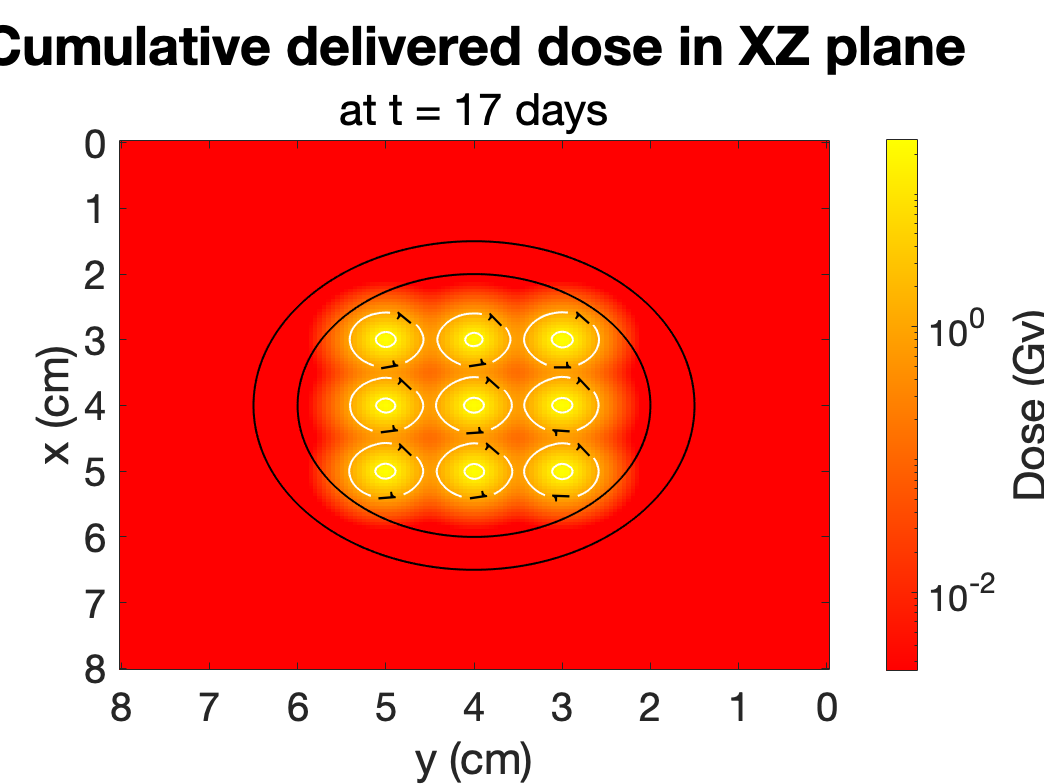

[xc2, yc2] = circle([4 4], 2,1200); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
[xc, yc] = circle([4 4], 2.5,1200); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
x_Dose = linspace(0,8,161);
y_Dose = linspace(0,8,161);
%Dose_D0 = load('Dose_D0.mat');
%Dose_cum = Dose_cum + Dose_after17d;

figure
imagesc(x_Dose,y_Dose,Dose_XZ_default.Dose_cum)
colormap('autumn')
hold on
[c,H] = contour(x_Dose,y_Dose,Dose_XZ_default.Dose_cum,[1 15 30 60 120],'ShowText','off','LineWidth',1,'LineColor','w');
plot(xc, yc, '-','linewidth',1,'Color','k');
plot(xc2 , yc2, '-','linewidth',1,'Color','k');
clabel(c,H,'FontSize',12,'Color','k','Margin',10,'LabelSpacing',60)
xlabel('x (cm)','FontSize',22)
ylabel('y (cm)','FontSize',22)
set(gca,'FontSize',20)
title('Cumulative delivered dose in XZ plane','FontSize',27)
txt = {'at t = 17 days'};
subtitle(txt,'FontSize',25)
view([90 90])
set(gca,'ColorScale','log')
clb = colorbar;
set(get(clb,'label'),'string','Dose (Gy)','FontSize',22);
set(gca,'XTick',[0 1 2 3 4 5 6 7 8],'XTickLabel',{'0','1','2','3','4','5','6','7','8'},'YTick',[0 1 2 3 4 5 6 7 8],'YTickLabel',{'0','1','2','3','4','5','6','7','8'})

## 1.2 Dose profile plot 2D 17 days: YZ

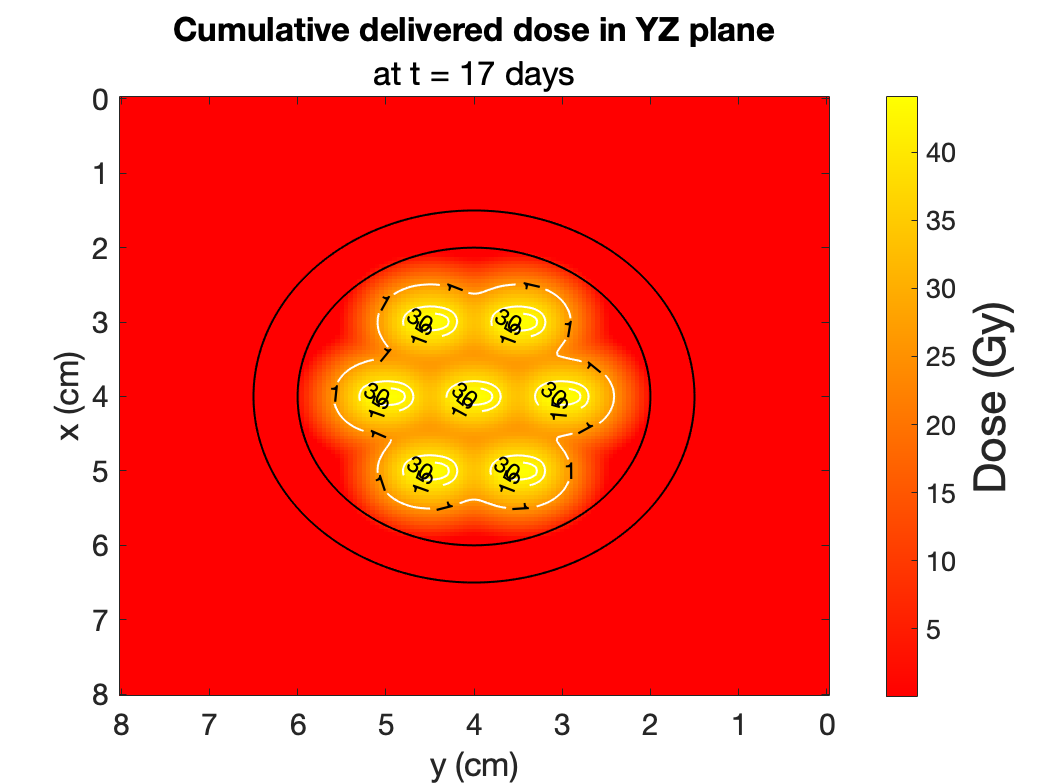

[xc2, yc2] = circle([4 4], 2,1200); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
[xc, yc] = circle([4 4], 2.5,1200); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
x_Dose = linspace(0,8,161);
y_Dose = linspace(0,8,161);
%Dose_D0 = load('Dose_D0.mat');
%Dose_cum = Dose_cum + Dose_after17d;

figure
imagesc(x_Dose,y_Dose,Dose_YZ_default.Dose_cum)
colormap('autumn')
hold on
[c,H] = contour(x_Dose,y_Dose,Dose_YZ_default.Dose_cum,[1 15 30 60 120],'ShowText','off','LineWidth',1,'LineColor','w');
plot(xc, yc, '-','linewidth',1,'Color','k');
plot(xc2 , yc2, '-','linewidth',1,'Color','k');
clabel(c,H,'FontSize',11.5,'Color','k','Margin',10,'LabelSpacing',34)
xlabel('x (cm)','FontSize',22)
ylabel('y (cm)','FontSize',22)
title('Cumulative delivered dose in YZ plane','FontSize',27)
txt = {'at t = 17 days'};
subtitle(txt)
view([90 90])
set(gca,'ColorScale','log')
clb = colorbar;
set(get(clb,'label'),'string','Dose (Gy)','FontSize',22);
set(gca,'XTick',[0 1 2 3 4 5 6 7 8],'XTickLabel',{'0','1','2','3','4','5','6','7','8'},'YTick',[0 1 2 3 4 5 6 7 8],'YTickLabel',{'0','1','2','3','4','5','6','7','8'})
set(gca,'FontSize',15)

## 2. Intersection through centre 17 days: XYZ

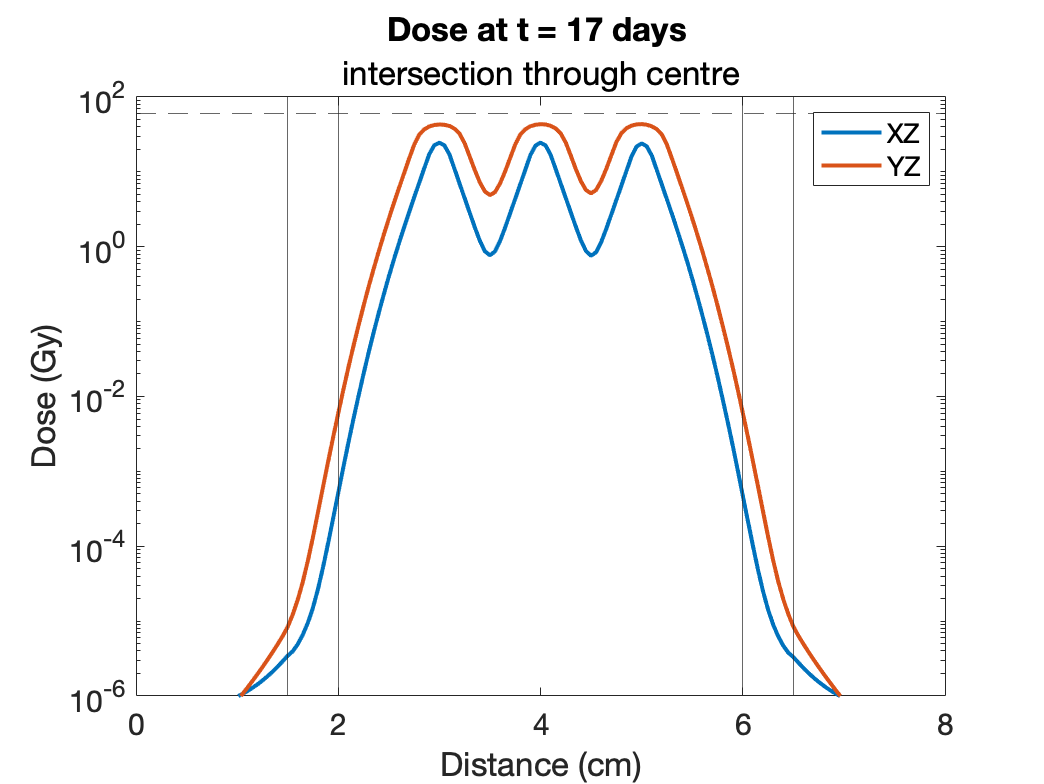

figure
plot(x_Dose,Dose_XZ_default.Dose_cum(:,81),'LineWidth',2)
hold on
plot(x_Dose,Dose_YZ_default.Dose_cum(:,81),'LineWidth',2)
yline(60,'--')
xline(2);
xline(6);
xline(1.5);
xline(6.5);
ylabel('Dose (Gy)')
xlabel('Distance (cm)')
title('Dose at t = 17 days ')
subtitle('intersection through centre')
set(gca,'YScale','log')
legend('XZ','YZ')
set(gca,'FontSize',15)
ylim([10^(-6) 10^2])
xlim([0 8])

## 3. Max, min, av dose after 17 days: XYZ

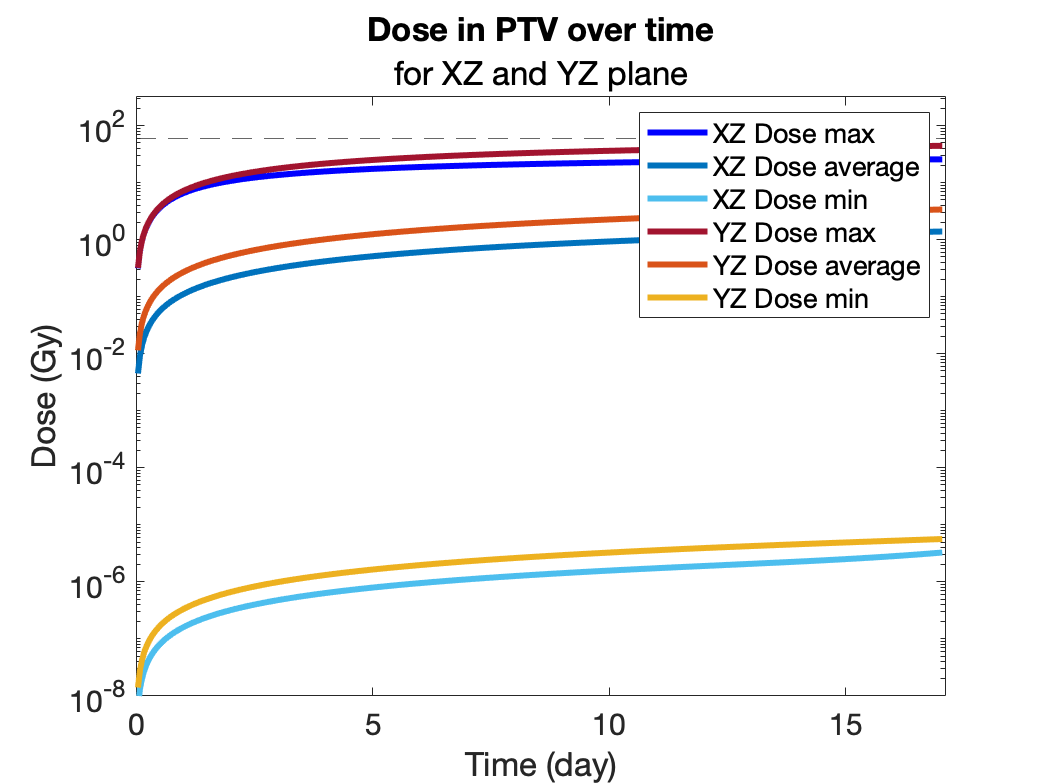

%%%%%%%%%%%%%%% Dose max %%%%%%%%%%%%%%%
runData.timePoints = 0:1:24*17+1;
time = runData.timePoints/24;
figure
plot(time,Dose_XZ_default.maxD,'LineWidth',3,'Color',"#0000FF")
hold on
plot(time,Dose_XZ_default.averageD,'LineWidth',3,'Color',"#0072BD")
plot(time,Dose_XZ_default.minD,'LineWidth',3,'Color',"#4DBEEE")
plot(time,Dose_YZ_default.maxD,'LineWidth',3,'Color',"#A2142F")
plot(time,Dose_YZ_default.averageD,'LineWidth',3,'Color',"#D95319")
plot(time,Dose_YZ_default.minD,'LineWidth',3,'Color',"#EDB120")
yline(60,'--')
set(gca,'YScale','log')
ylim([10^-8 10^2.5])
xlim([0 17.1])
title('Dose in PTV over time','FontSize',22)
txt = {'for XZ and YZ plane'};
subtitle(txt,'FontSize',22)
ylabel("Dose (Gy)",'FontSize',17)
xlabel("Time (day)",'FontSize',17) 
legend("XZ Dose max","XZ Dose average","XZ Dose min","YZ Dose max","YZ Dose average","YZ Dose min")
set(gca,'FontSize',15)

## 4. Calculate GTV, PTV, PTV + 1 cm values of Dose

r = [2 2.5 3.5];
centretumor = [4 4];
%Dose_YZ_84d = Dose_YZ_default.Dose_time(:,409) + Dose_YZ_default_84d.Dose_after17d_array(:,end) ;
%Dose_XZ_default_84d_reshape = reshape(Dose_XZ_default_cum_84d(:,:),[],1);
[modelData] = dd6_2_Dose_t_average(Dose_XZ_default.Dose_time,x2,y2,r(1),r(2),r(3),centretumor(1)); % C values (max,min,average) in GTV

averageD_GTV = 2.1611

minD_GTV = 3.4584e-04

maxD_GTV = 25.5154

averageD_PTV = 0.0050

minD_PTV = 3.2526e-06

maxD_PTV = 0.1328

averageD_1cm = 2.7220e-06

minD_1cm = 5.8294e-07

maxD_1cm = 4.9485e-05

Output argument "modelData" (and possibly others) not assigned a value in the execution with "dd6_2_Dose_t_average" function.

[modelData] = dd6_2_Dose_t_average(Dose_YZ_default.Dose_time,x2,y2,r(1),r(2),r(3),centretumor(1)); % C values (max,min,average) in GTV

averageD_GTV = 5.2595

minD_GTV = 2.4315e-04

maxD_GTV = 44.0049

averageD_PTV = 5.8682e-04

minD_PTV = 5.6322e-06

maxD_PTV = 0.0120

averageD_1cm = 1.7641e-06

minD_1cm = 1.4181e-07

maxD_1cm = 1.3235e-05

Output argument "modelData" (and possibly others) not assigned a value in the execution with "dd6_2_Dose_t_average" function.

# Diffusion coefficient

## 1.1 Dose profile plot 2D 17 days: Dmin

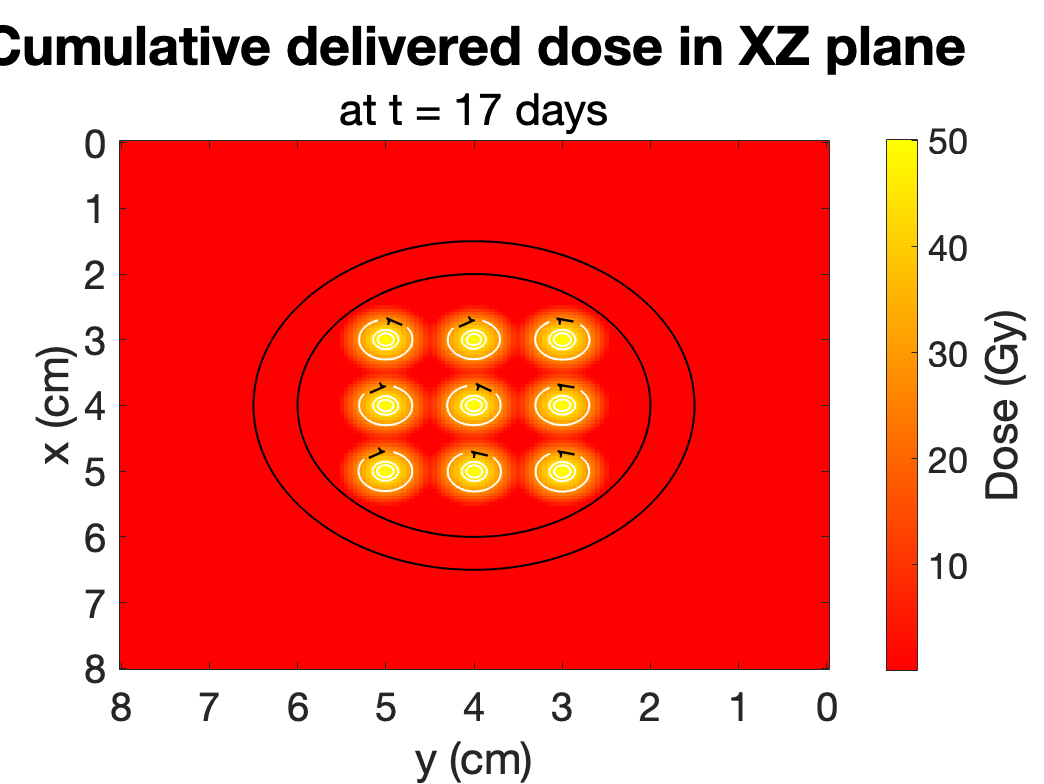

[xc2, yc2] = circle([4 4], 2,1200); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
[xc, yc] = circle([4 4], 2.5,1200); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
x_Dose = linspace(0,8,161);
y_Dose = linspace(0,8,161);
%Dose_D0 = load('Dose_D0.mat');
%Dose_cum = Dose_cum + Dose_after17d;

figure
imagesc(x_Dose,y_Dose,Dose_D_min.Dose_cum)
colormap('autumn')
hold on
[c,H] = contour(x_Dose,y_Dose,Dose_D_min.Dose_cum,[1 15 30 60 120],'ShowText','off','LineWidth',1,'LineColor','w');
plot(xc, yc, '-','linewidth',1,'Color','k');
plot(xc2 , yc2, '-','linewidth',1,'Color','k');
clabel(c,H,'FontSize',12,'Color','k','Margin',10,'LabelSpacing',70)
xlabel('x (cm)','FontSize',22)
ylabel('y (cm)','FontSize',22)
set(gca,'FontSize',20)
title('Cumulative delivered dose in XZ plane','FontSize',27)
txt = {'at t = 17 days'};
subtitle(txt,'FontSize',25) 
clb = colorbar;
set(get(clb,'label'),'string','Dose (Gy)','FontSize',22);
view([90 90])
set(gca,'ColorScale','log')
set(gca,'XTick',[0 1 2 3 4 5 6 7 8],'XTickLabel',{'0','1','2','3','4','5','6','7','8'},'YTick',[0 1 2 3 4 5 6 7 8],'YTickLabel',{'0','1','2','3','4','5','6','7','8'})

## 1.2 Dose profile plot 2D 17 days: Dmax

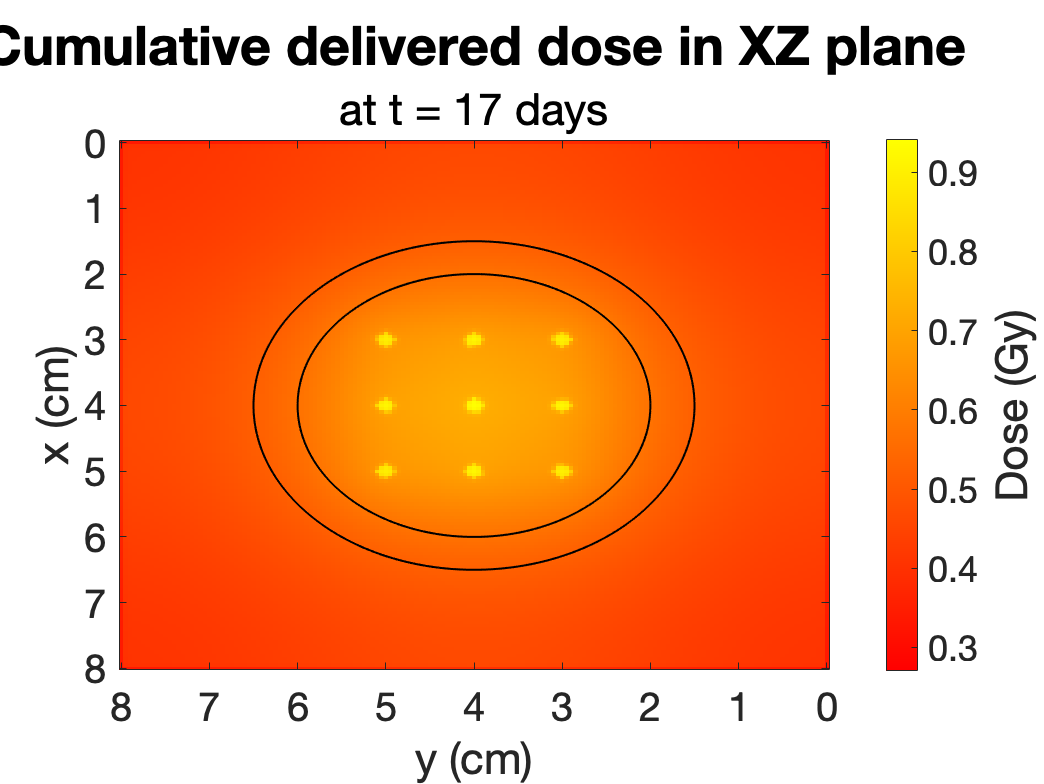

[xc2, yc2] = circle([4 4], 2,1200); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
[xc, yc] = circle([4 4], 2.5,1200); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
x_Dose = linspace(0,8,161);
y_Dose = linspace(0,8,161);
%Dose_D0 = load('Dose_D0.mat');
%Dose_cum = Dose_cum + Dose_after17d;

figure
imagesc(x_Dose,y_Dose,Dose_D_max.Dose_cum)
colormap('autumn')
hold on
[c,H] = contour(x_Dose,y_Dose,Dose_D_max.Dose_cum,[1 15 30 60 120],'ShowText','off','LineWidth',1,'LineColor','w');
plot(xc, yc, '-','linewidth',1,'Color','k');
plot(xc2 , yc2, '-','linewidth',1,'Color','k');
clabel(c,H,'FontSize',12,'Color','k','Margin',10,'LabelSpacing',70)
xlabel('x (cm)','FontSize',22)
ylabel('y (cm)','FontSize',22)
set(gca,'FontSize',20)
title('Cumulative delivered dose in XZ plane','FontSize',27)
txt = {'at t = 17 days'};
subtitle(txt,'FontSize',25) 
clb = colorbar;
set(get(clb,'label'),'string','Dose (Gy)','FontSize',22);
view([90 90])
set(gca,'ColorScale','log')
set(gca,'XTick',[0 1 2 3 4 5 6 7 8],'XTickLabel',{'0','1','2','3','4','5','6','7','8'},'YTick',[0 1 2 3 4 5 6 7 8],'YTickLabel',{'0','1','2','3','4','5','6','7','8'})

## 1.3 Dose profile plot 2D 17 days: D0

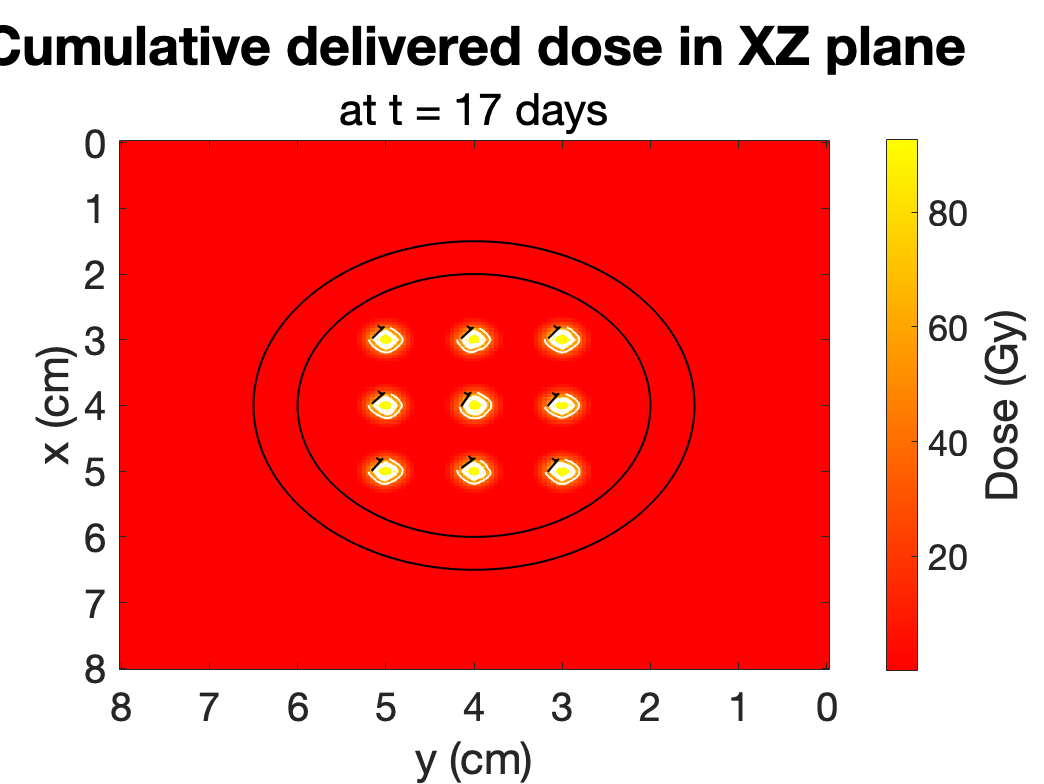

[xc2, yc2] = circle([4 4], 2,1200); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
[xc, yc] = circle([4 4], 2.5,1200); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
x_Dose = linspace(0,8,161);
y_Dose = linspace(0,8,161);
%Dose_D0 = load('Dose_D0.mat');
%Dose_cum = Dose_cum + Dose_after17d;

figure
imagesc(x_Dose,y_Dose,Dose_D0.Dose_cum)
colormap('autumn')
hold on
[c,H] = contour(x_Dose,y_Dose,Dose_D0.Dose_cum,[1 15 30 60 120],'ShowText','off','LineWidth',1,'LineColor','w');
plot(xc, yc, '-','linewidth',1,'Color','k');
plot(xc2 , yc2, '-','linewidth',1,'Color','k');
clabel(c,H,'FontSize',12,'Color','k','Margin',10,'LabelSpacing',80)
xlabel('x (cm)','FontSize',22)
ylabel('y (cm)','FontSize',22)
set(gca,'FontSize',20)
title('Cumulative delivered dose in XZ plane','FontSize',27)
txt = {'at t = 17 days'};
subtitle(txt,'FontSize',25) 
clb = colorbar;
set(get(clb,'label'),'string','Dose (Gy)','FontSize',22);
view([90 90])
set(gca,'ColorScale','log')
set(gca,'XTick',[0 1 2 3 4 5 6 7 8],'XTickLabel',{'0','1','2','3','4','5','6','7','8'},'YTick',[0 1 2 3 4 5 6 7 8],'YTickLabel',{'0','1','2','3','4','5','6','7','8'})

## 2. Intersection through centre 17 days: Dmax, Dmin, D0

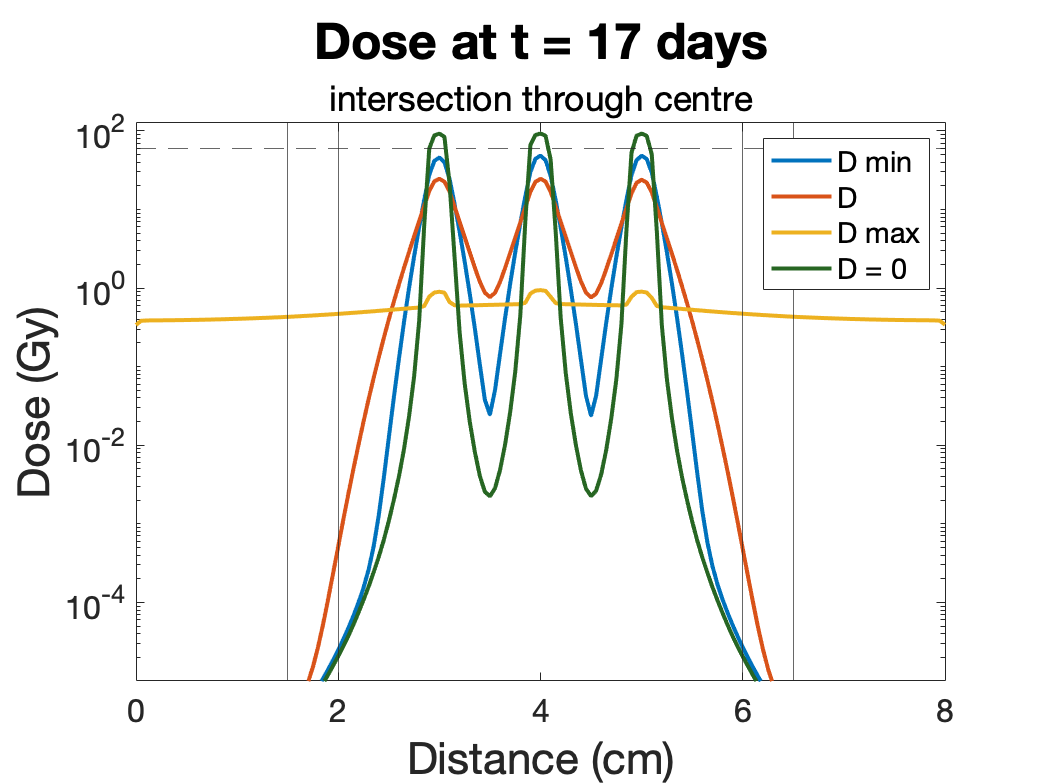

figure
plot(x_Dose,Dose_D_min.Dose_cum(81,:),'LineWidth',2)
hold on
plot(x_Dose,Dose_XZ_default.Dose_cum(:,81),'LineWidth',2)
plot(x_Dose,Dose_D_max.Dose_cum(81,:),'LineWidth',2)
plot(x_Dose,Dose_D0.Dose_cum(81,:),'LineWidth',2,'Color',[0.1529    0.4000    0.1373])
yline(60,'--')
xline(2);
xline(6);
xline(1.5);
xline(6.5);
set(gca,'FontSize',16)
ylabel('Dose (Gy)','FontSize',22) 
xlabel('Distance (cm)','FontSize',22) 
title('Dose at t = 17 days','FontSize',25) 
subtitle('intersection through centre','FontSize',25)
set(gca,'YScale','log')
legend("D min","D","D max",'D = 0')
ylim([10^(-5) 10^2.1])

## 3. Max, min, av dose after 17 days: D max, Dmin, D0

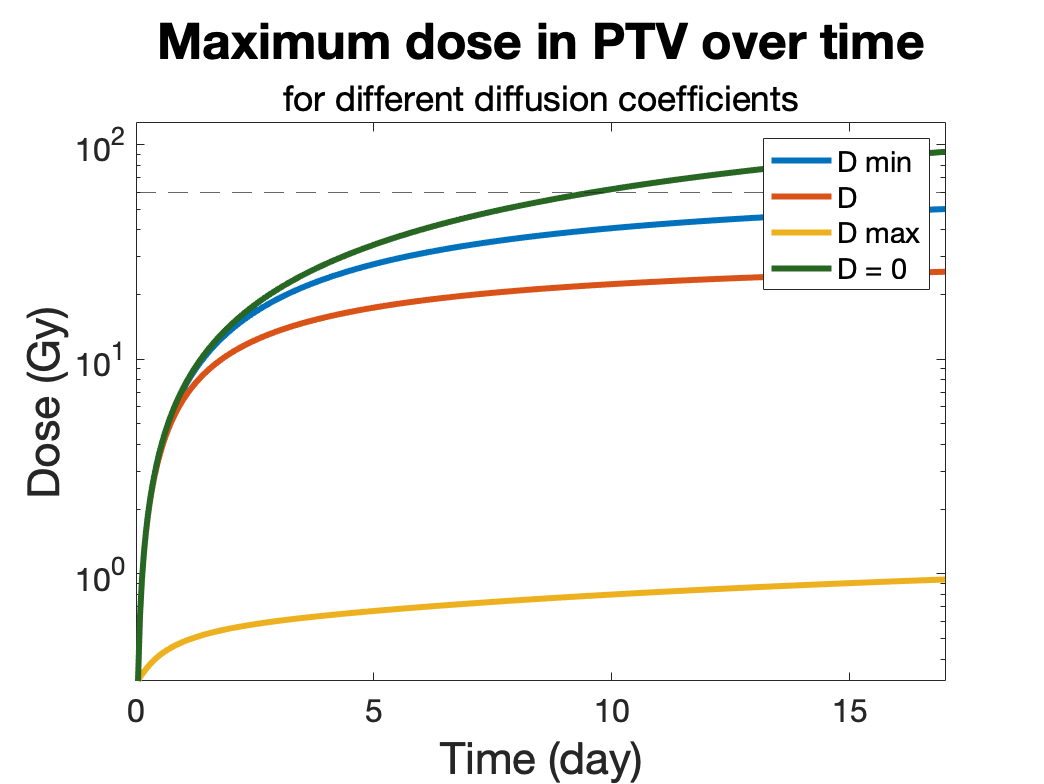

%%%%%%%%%%%%%%% Dose max %%%%%%%%%%%%%%%
runData.timePoints = 0:1:24*17+1;
time = runData.timePoints/24;
figure
plot(time,Dose_D_min.maxD,'LineWidth',3)
hold on
plot(time,Dose_XZ_default.maxD,'LineWidth',3)
plot(time,Dose_D_max.maxD,'LineWidth',3)
plot(time,Dose_D0.maxD,'LineWidth',3,'Color',[0.1529    0.4000    0.1373])
yline(60,'--')
set(gca,'YScale','log')
set(gca,'FontSize',16)
title('Maximum dose in PTV over time','FontSize',25)
txt = {'for different diffusion coefficients'};
subtitle(txt,'FontSize',25)
ylabel("Dose (Gy)",'FontSize',22)
xlabel("Time (day)",'FontSize',22) 
legend("D min","D","D max",'D = 0')
xlim([0 17])
ylim([10^(-0.5) 10^2.1])

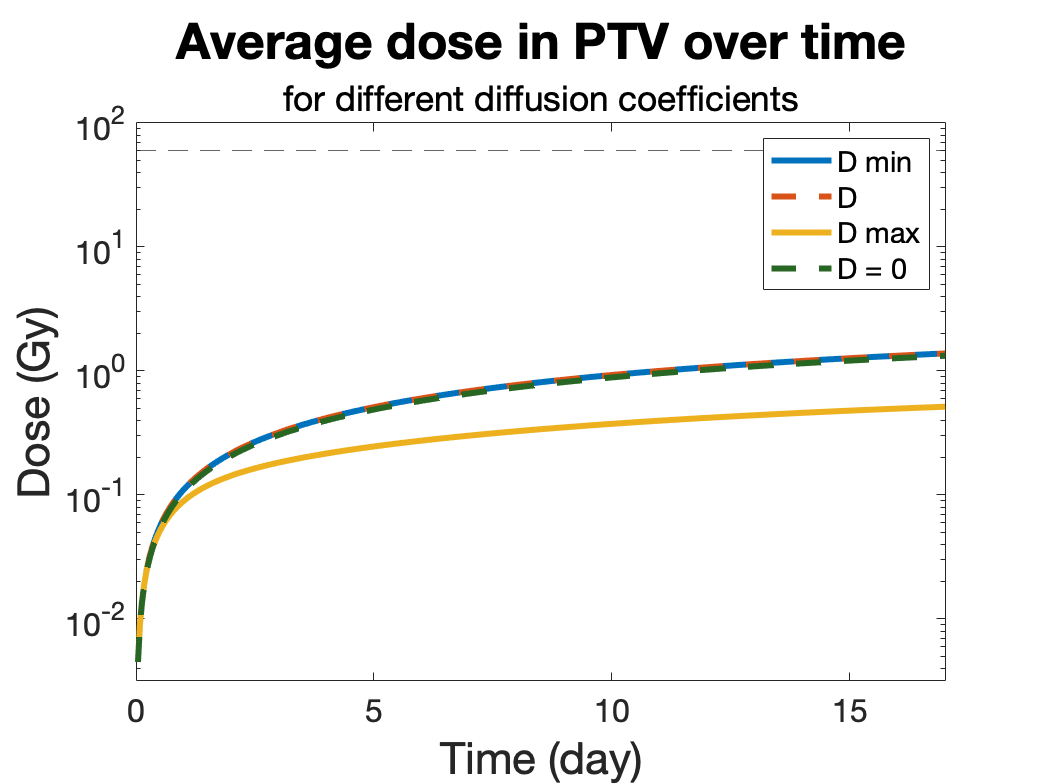

%%%%%%%%%%%%%%% Dose av %%%%%%%%%%%%%%%
figure
plot(time,Dose_D_min.averageD,'LineWidth',3)
hold on
plot(time,Dose_XZ_default.averageD,'LineWidth',3,'LineStyle','--')
plot(time,Dose_D_max.averageD,'LineWidth',3)
plot(time,Dose_D0.averageD,'LineWidth',3,'Color',[0.1529    0.4000    0.1373],'LineStyle','--')
yline(60,'--')
set(gca,'YScale','log')
set(gca,'FontSize',16)
title('Average dose in PTV over time','FontSize',25)
txt = {'for different diffusion coefficients'};
subtitle(txt,'FontSize',25)
ylabel("Dose (Gy)",'FontSize',22)
xlabel("Time (day)",'FontSize',22) 
legend("D min","D","D max",'D = 0')
xlim([0 17])
ylim([10^(-2.5) 10^2])

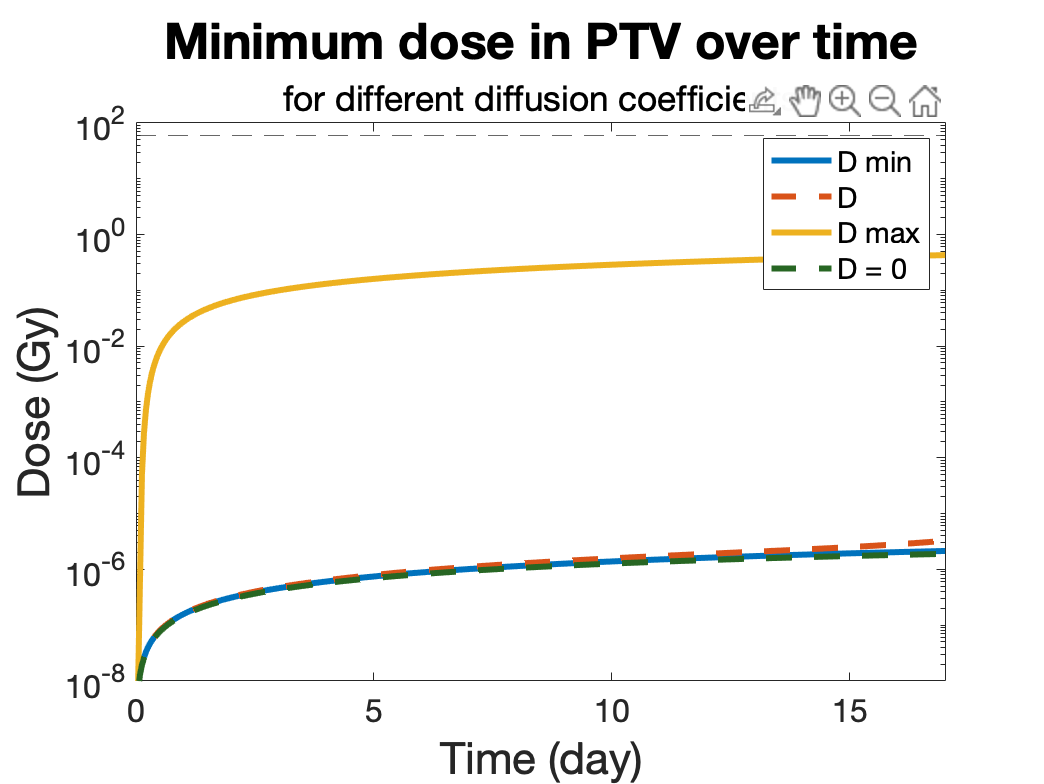

%%%%%%%%%%%%%%% Dose min %%%%%%%%%%%%%%%
figure
plot(time,Dose_D_min.minD,'LineWidth',3)
hold on
plot(time,Dose_XZ_default.minD,'LineWidth',3,'LineStyle','--')
plot(time,Dose_D_max.minD,'LineWidth',3)
plot(time,Dose_D0.minD,'LineWidth',3,'Color',[0.1529    0.4000    0.1373],'LineStyle','--')
yline(60,'--')
set(gca,'YScale','log')
set(gca,'FontSize',16)
title('Minimum dose in PTV over time','FontSize',25)
txt = {'for different diffusion coefficients'};
subtitle(txt,'FontSize',25)
ylabel("Dose (Gy)",'FontSize',22)
xlabel("Time (day)",'FontSize',22) 
legend("D min","D","D max",'D = 0')
xlim([0 17])
ylim([10^(-8) 10^2])

## 4. Calculate GTV, PTV, PTV + 1 cm values of Dose


r = [2 2.5 3.5];
centretumor = [4 4];
%Dose_YZ_84d = Dose_YZ_default.Dose_time(:,409) + Dose_YZ_default_84d.Dose_after17d_array(:,end) ;
%Dose_XZ_default_84d_reshape = reshape(Dose_XZ_default_cum_84d(:,:),[],1);
[modelData1] = dd6_2_Dose_t_average(Dose_D_min.Dose_time,x2,y2,r(1),r(2),r(3),centretumor(1)); % C values (max,min,average) in GTV

averageD_GTV = 2.1640

minD_GTV = 2.4798e-05

maxD_GTV = 50.0024

averageD_PTV = 5.3947e-05

minD_PTV = 2.1382e-06

maxD_PTV = 0.0014

averageD_1cm = 1.1910e-06

minD_1cm = 6.4315e-08

maxD_1cm = 1.2789e-05

Output argument "modelData" (and possibly others) not assigned a value in the execution with "dd6_2_Dose_t_average" function.

[modelData2] = dd6_2_Dose_t_average(Dose_D_max.Dose_time,x2,y2,r(1),r(2),r(3),centretumor(1)); % C values (max,min,average) in GTV

averageD_GTV = 0.5514

minD_GTV = 0.4685

maxD_GTV = 0.9398

averageD_PTV = 0.4503

minD_PTV = 0.4288

maxD_PTV = 0.4805

averageD_1cm = 0.4037

minD_1cm = 0.3795

maxD_1cm = 0.4324

Output argument "modelData" (and possibly others) not assigned a value in the execution with "dd6_2_Dose_t_average" function.

[modelData3] = dd6_2_Dose_t_average(Dose_D0.Dose_time,x2,y2,r(1),r(2),r(3),centretumor(1)); % C values (max,min,average) in GTV

averageD_GTV = 2.0698

minD_GTV = 2.0437e-05

maxD_GTV = 92.4416

averageD_PTV = 3.2433e-05

minD_PTV = 1.8990e-06

maxD_PTV = 4.1271e-04

averageD_1cm = 1.0428e-06

minD_1cm = 5.9336e-08

maxD_1cm = 1.0741e-05

Output argument "modelData" (and possibly others) not assigned a value in the execution with "dd6_2_Dose_t_average" function.

# Initial concentration

## 1.1 Dose profile plot 2D 17 days: cmin

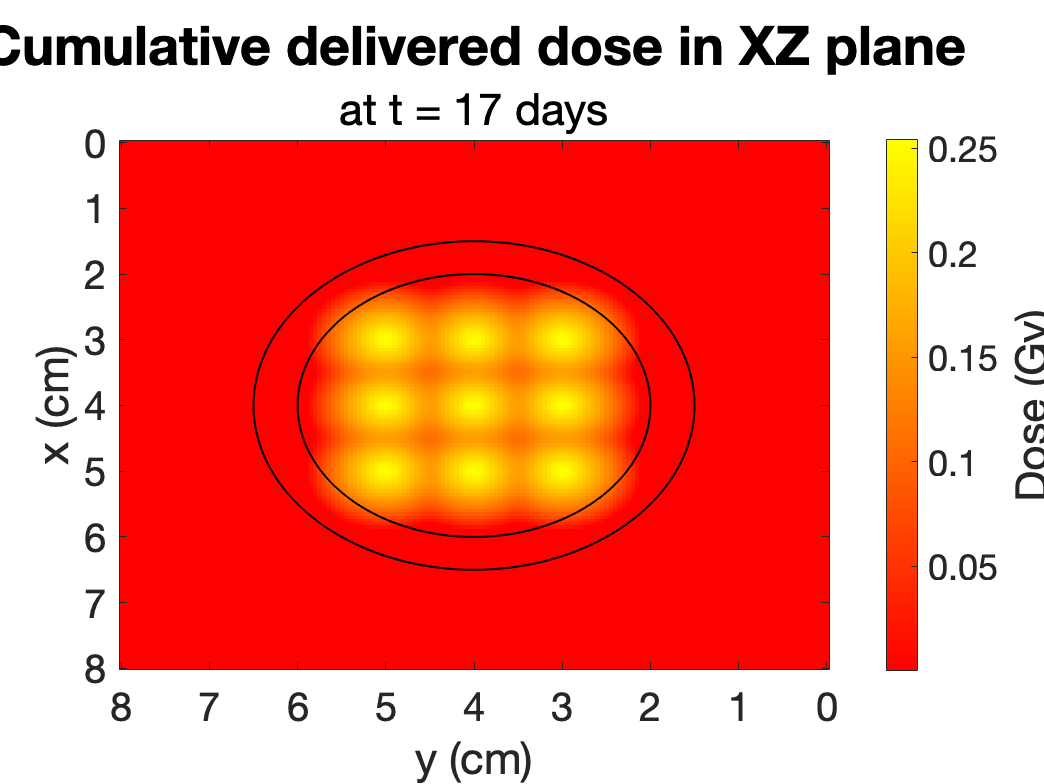

[xc2, yc2] = circle([4 4], 2,1200); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
[xc, yc] = circle([4 4], 2.5,1200); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
x_Dose = linspace(0,8,161);
y_Dose = linspace(0,8,161);
%Dose_D0 = load('Dose_D0.mat');
%Dose_cum = Dose_cum + Dose_after17d;

figure
imagesc(x_Dose,y_Dose,Dose_ci_min.Dose_cum)
colormap('autumn')
hold on
[c,H] = contour(x_Dose,y_Dose,Dose_ci_min.Dose_cum,[1 60 120],'ShowText','off','LineWidth',1,'LineColor','w');
plot(xc, yc, '-','linewidth',1,'Color','k');
plot(xc2 , yc2, '-','linewidth',1,'Color','k');
clabel(c,H,'FontSize',16,'Color','w','Margin',10,'LabelSpacing',80)
xlabel('x (cm)','FontSize',22)
ylabel('y (cm)','FontSize',22)
set(gca,'FontSize',20)
title('Cumulative delivered dose in XZ plane','FontSize',27)
txt = {'at t = 17 days'};
subtitle(txt,'FontSize',25) 
clb = colorbar;
set(get(clb,'label'),'string','Dose (Gy)','FontSize',22);
view([90 90])
set(gca,'ColorScale','log')
set(gca,'XTick',[0 1 2 3 4 5 6 7 8],'XTickLabel',{'0','1','2','3','4','5','6','7','8'},'YTick',[0 1 2 3 4 5 6 7 8],'YTickLabel',{'0','1','2','3','4','5','6','7','8'})

## 1.2 Dose profile plot 2D 17 days: cmax

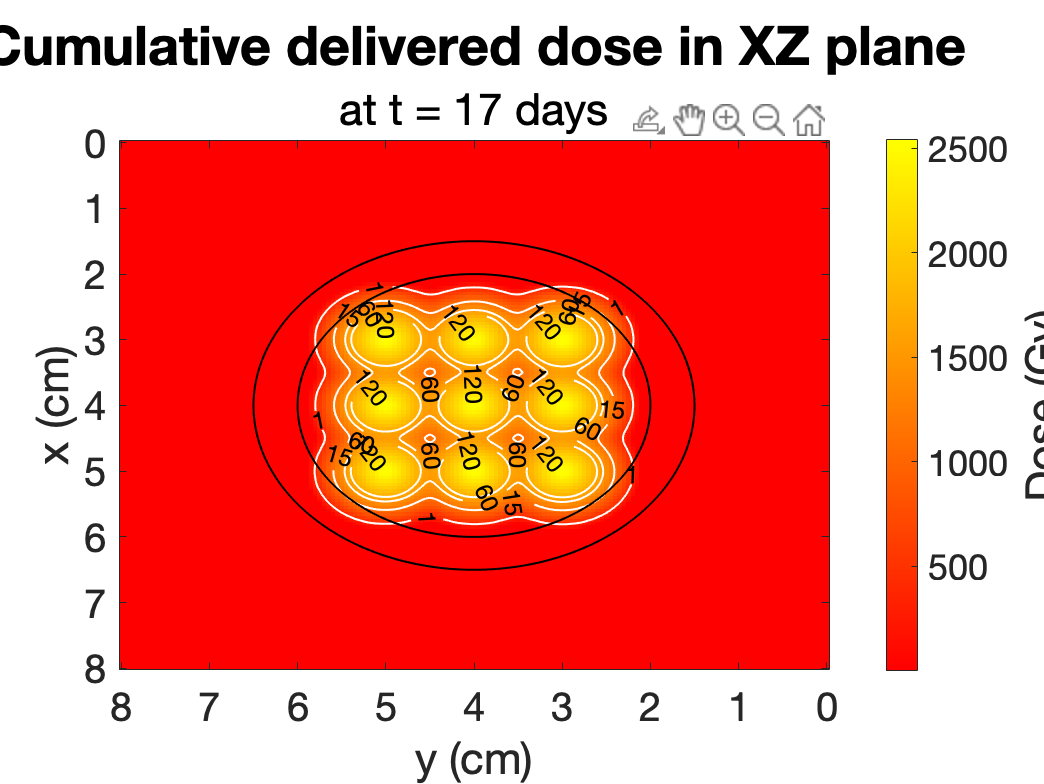

[xc2, yc2] = circle([4 4], 2,1200); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
[xc, yc] = circle([4 4], 2.5,1200); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
x_Dose = linspace(0,8,161);
y_Dose = linspace(0,8,161);
%Dose_D0 = load('Dose_D0.mat');
%Dose_cum = Dose_cum + Dose_after17d;

figure
imagesc(x_Dose,y_Dose,Dose_ci_max.Dose_cum)
colormap('autumn')
hold on
[c,H] = contour(x_Dose,y_Dose,Dose_ci_max.Dose_cum,[1 15 60 120],'ShowText','off','LineWidth',1,'LineColor','w');
plot(xc, yc, '-','linewidth',1,'Color','k');
plot(xc2 , yc2, '-','linewidth',1,'Color','k');

clabel(c,H,'FontSize',12,'Color','k','Margin',10,'LabelSpacing',100)
xlabel('x (cm)','FontSize',22)
ylabel('y (cm)','FontSize',22)
set(gca,'FontSize',20)
title('Cumulative delivered dose in XZ plane','FontSize',27)
txt = {'at t = 17 days'};
subtitle(txt,'FontSize',25) 
clb = colorbar;
set(get(clb,'label'),'string','Dose (Gy)','FontSize',22);
view([90 90])
set(gca,'ColorScale','log')
set(gca,'XTick',[0 1 2 3 4 5 6 7 8],'XTickLabel',{'0','1','2','3','4','5','6','7','8'},'YTick',[0 1 2 3 4 5 6 7 8],'YTickLabel',{'0','1','2','3','4','5','6','7','8'})

## 2. Intersection through centre 17 days: ci max, ci min

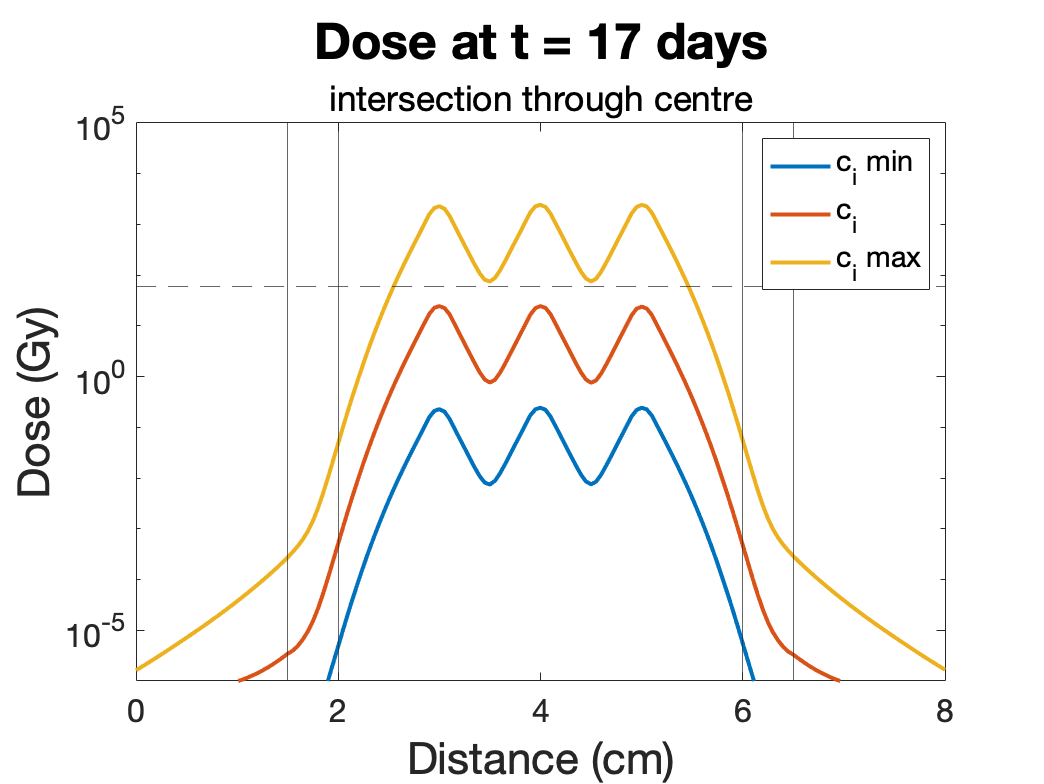

figure
plot(x_Dose,Dose_ci_min.Dose_cum(81,:),'LineWidth',2)
hold on
plot(x_Dose,Dose_XZ_default.Dose_cum(:,81),'LineWidth',2)
plot(x_Dose,Dose_ci_max.Dose_cum(81,:),'LineWidth',2)
yline(60,'--')
xline(2);
xline(6);
xline(1.5);
xline(6.5);
set(gca,'FontSize',16)
ylabel('Dose (Gy)','FontSize',22) 
xlabel('Distance (cm)','FontSize',22) 
title('Dose at t = 17 days','FontSize',25) 
subtitle('intersection through centre','FontSize',25)
set(gca,'YScale','log')
legend("c_i min","c_i","c_i max")
ylim([10^(-6) 10^5])

## 3. Max, min, av dose after 17 days: ci max, ci min

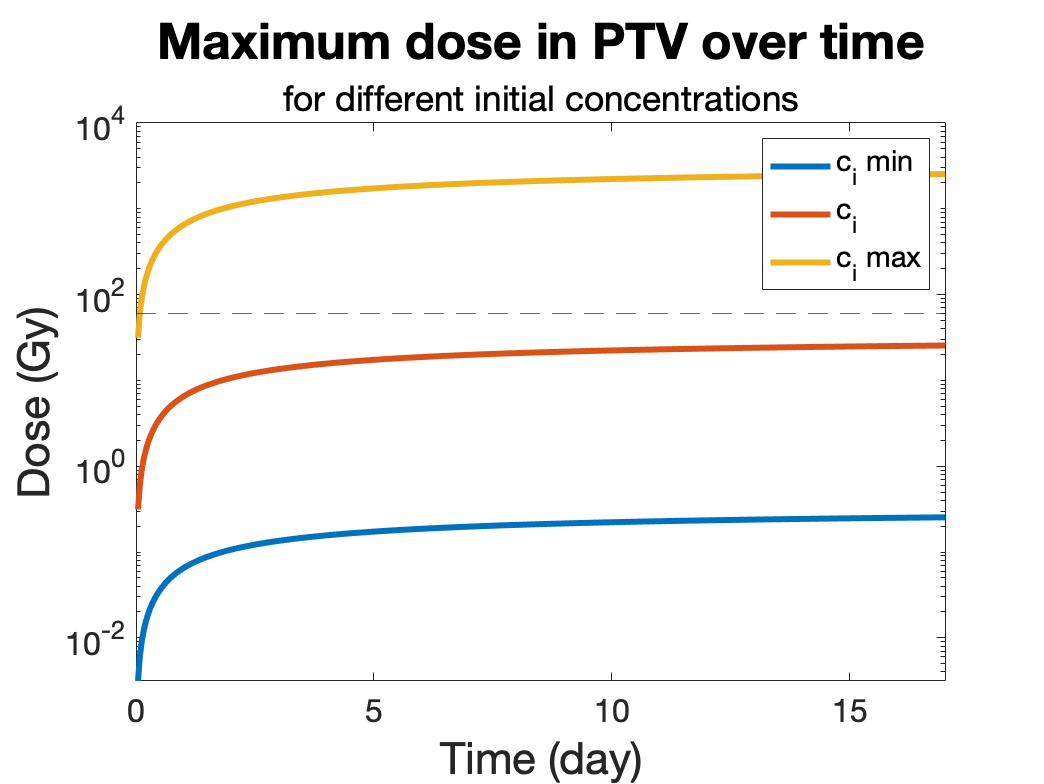

%%%%%%%%%%%%%%% Dose max %%%%%%%%%%%%%%%
runData.timePoints = 0:1:24*17+1;
time = runData.timePoints/24;
figure
plot(time,Dose_ci_min.maxD,'LineWidth',3)
hold on
plot(time,Dose_XZ_default.maxD,'LineWidth',3)
plot(time,Dose_ci_max.maxD,'LineWidth',3)
yline(60,'--')
set(gca,'YScale','log')
set(gca,'FontSize',16)
title('Maximum dose in PTV over time','FontSize',25)
txt = {'for different initial concentrations'};
subtitle(txt,'FontSize',25)
ylabel("Dose (Gy)",'FontSize',22)
xlabel("Time (day)",'FontSize',22) 
legend("c_i min","c_i","c_i max")
xlim([0 17])

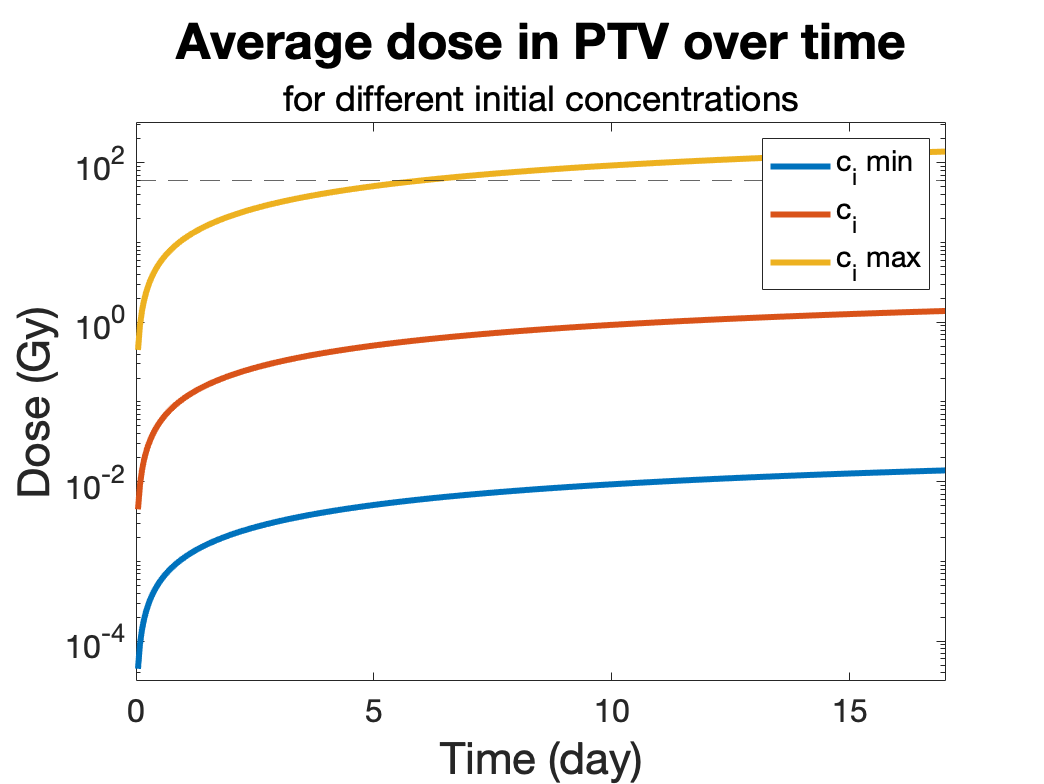


%%%%%%%%%%%%%%% Dose av %%%%%%%%%%%%%%%
figure
plot(time,Dose_ci_min.averageD,'LineWidth',3)
hold on
plot(time,Dose_XZ_default.averageD,'LineWidth',3)
plot(time,Dose_ci_max.averageD,'LineWidth',3)
yline(60,'--')
set(gca,'YScale','log')
set(gca,'FontSize',16)
title('Average dose in PTV over time','FontSize',25)
txt = {'for different initial concentrations'};
subtitle(txt,'FontSize',25)
ylabel("Dose (Gy)",'FontSize',22)
xlabel("Time (day)",'FontSize',22) 
legend("c_i min","c_i","c_i max")
xlim([0 17])
ylim([10^(-4.5) 10^2.5])

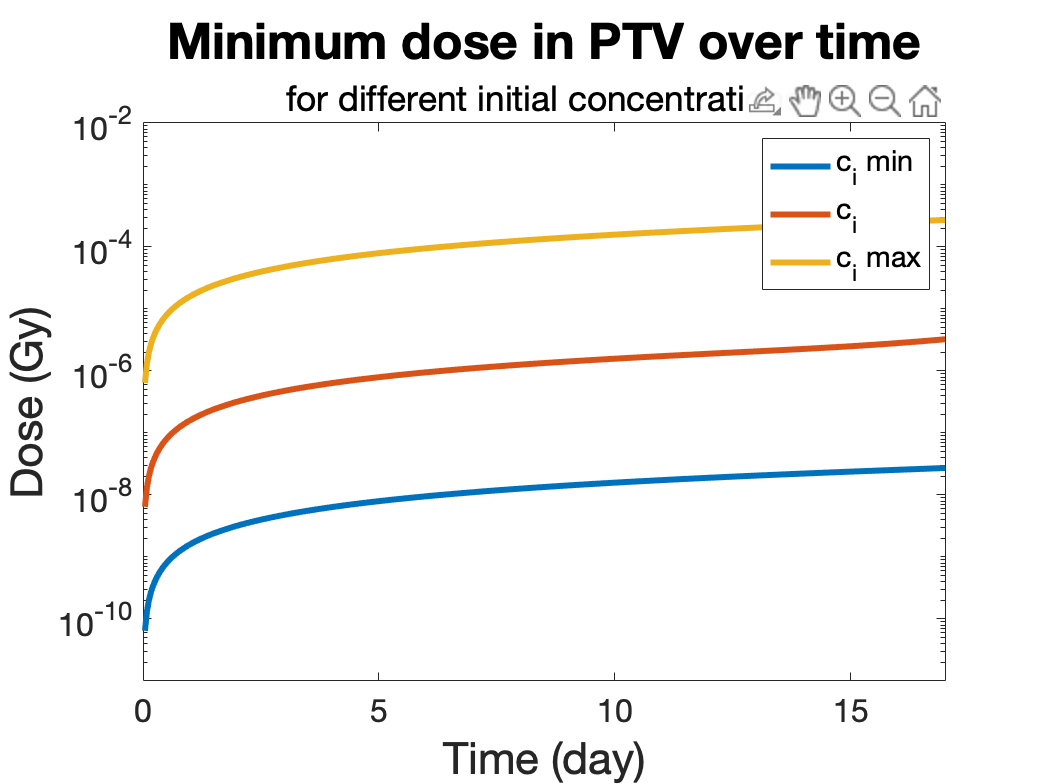


%%%%%%%%%%%%%%% Dose min %%%%%%%%%%%%%%%
figure
plot(time,Dose_ci_min.minD,'LineWidth',3)
hold on
plot(time,Dose_XZ_default.minD,'LineWidth',3)
plot(time,Dose_ci_max.minD,'LineWidth',3)
yline(60,'--')
set(gca,'YScale','log')
set(gca,'FontSize',16)
title('Minimum dose in PTV over time','FontSize',25)
txt = {'for different initial concentrations'};
subtitle(txt,'FontSize',25)
ylabel("Dose (Gy)",'FontSize',22)
xlabel("Time (day)",'FontSize',22) 
legend("c_i min","c_i","c_i max")
xlim([0 17])
ylim([10^(-11) 10^(-2)])

## 4. Calculate GTV, PTV, PTV + 1 cm values of Dose

r = [2 2.5 3.5];
centretumor = [4 4];
%Dose_YZ_84d = Dose_YZ_default.Dose_time(:,409) + Dose_YZ_default_84d.Dose_after17d_array(:,end) ;
%Dose_XZ_default_84d_reshape = reshape(Dose_XZ_default_cum_84d(:,:),[],1);
[modelData4] = dd6_2_Dose_t_average(Dose_ci_min.Dose_time,x2,y2,r(1),r(2),r(3),centretumor(1)); % C values (max,min,average) in GTV

averageD_GTV = 0.0216

minD_GTV = 3.6715e-06

maxD_GTV = 0.2537

averageD_PTV = 5.1362e-05

minD_PTV = 2.7271e-08

maxD_PTV = 0.0014

averageD_1cm = 3.2457e-08

minD_1cm = 7.1329e-10

maxD_1cm = 9.1207e-07

Output argument "modelData" (and possibly others) not assigned a value in the execution with "dd6_2_Dose_t_average" function.

[modelData5] = dd6_2_Dose_t_average(Dose_ci_max.Dose_time,x2,y2,r(1),r(2),r(3),centretumor(1)); % C values (max,min,average) in GTV

averageD_GTV = 216.1030

minD_GTV = 0.0367

maxD_GTV = 2.5373e+03

averageD_PTV = 0.5136

minD_PTV = 2.7271e-04

maxD_PTV = 13.5605

averageD_1cm = 3.2457e-04

minD_1cm = 7.1329e-06

maxD_1cm = 0.0091

Output argument "modelData" (and possibly others) not assigned a value in the execution with "dd6_2_Dose_t_average" function.